# 2D Discrete Operators

clear, close all, clc
set_defaults()

## 2D staggered grid

Due to the internal logic of the Matlab functions meshgrid() and reshape() it is best to order the number the unknowns/cells/faces/dof's in the 2D grid in y-direction first and then in x-direction.

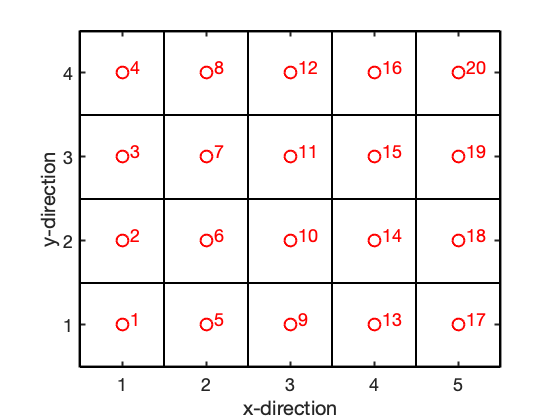

Nx = 5; Ny = 4;
plot_grid(Nx,Ny)

On this grid we need a two discrete operatore:

- Discrete divergence: `D`` = [``Dx``,``Dy``]`

- Discrete gradient:     **G** = [**Gx**;**Gy**]

## Assembly of discrete divergence

The 2D `Dx` and `Dy` are block matrices that are composed of

- 1D divergence and gradient operators

- (scaled) Indentity matrices

- zeros

These matrices can therefore be assembled simply and efficiently using tensor/Kronecker products. 

Last class we have shown that the 2D operators can be defirned in terms of the 1D operators as follows

- `Dx`` = kron(``Dx``,``Iy``);`

- `Dy`` = kron(``Ix``,``Dy``);`

where `Ix` and `Iy` are Nx by Nx and Ny by Ny identity matrices, respectively.

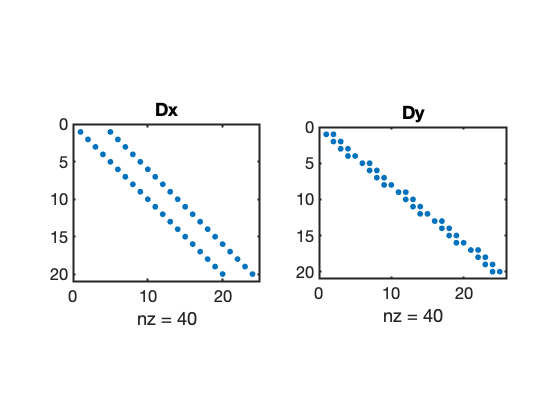

Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = Nx;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = Ny;
Grid = build_grid(Grid);

% Build 2D Dx matrix
Dx = spdiags([-ones(Nx,1) ones(Nx,1)]/Grid.dx,[0 1],Nx,Nx+1);
Iy = speye(Ny);
Dx = kron(Dx,Iy);

% Bulid 2D Dy matrix
Dy = spdiags([-ones(Ny,1) ones(Ny,1)]/Grid.dy,[0 1],Ny,Ny+1);
Ix = speye(Grid.Nx);
Dy = kron(Ix,Dy);

% Full 2D discrete divergence matrix
D = [Dx,Dy];

subplot 121
spy(Dx), title 'Dx'
subplot 122
spy(Dy), title 'Dy'

Note, that 3D operators can be assembled similarly by applying the tensor product to the 2D matrices and `Iz`!

## Discrete gradient

While it is straight forward to assemble the gradients directly, it is even more convenient to recognize that the gradient is the adjoint operator of the divergence in the interior of the domain, but has natural boundary conditions (zero gradient) on the exterior. Hence, we obtain `G` as in 1D:

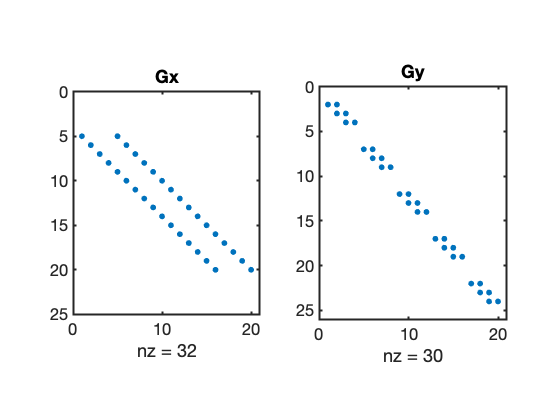

% ADJOINT IN INTERIOR
G = -D';  

% NATUAL BC's ON EXTERIOR
% collect all exterior faces
dof_f_bnd = [Grid.dof_f_xmin; Grid.dof_f_xmax;... 
             Grid.dof_f_ymin; Grid.dof_f_ymax];
% set gradient to zero
G(dof_f_bnd,:) = 0;

% plot
figure
subplot 121
spy(G(1:Grid.Nfx,:)), title 'Gx'
subplot 122
spy(G(Grid.Nfx+1:Grid.Nf,:)), title 'Gy'

## 2D discrete Laplacian

As in 1D the discrete Laplacian in 2D is simply the product of `D` and `G`:

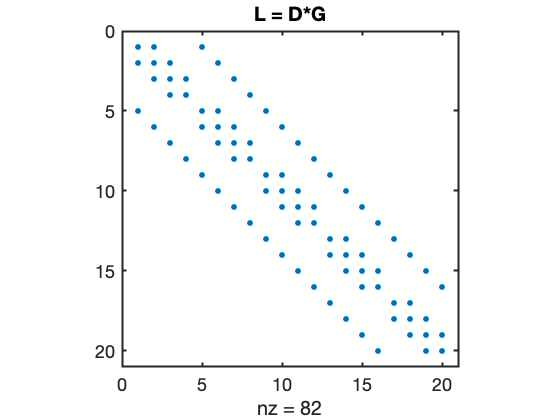

L = -D*G;
figure
spy(L), title 'L = D*G'

## Forward tesing of 2D operators

Similar to 1D we can view the D and G matrices as differentiation matrices and check if they compute derivatives correctly.

We use the following simple trigonometric function and its derivatives

#### Analytical derivatives

% Problem parameters
nx = 1; ny = 2;
Lx = 1; Ly = 1;
% funct
h      = @(x,y)  cos(2*pi*nx/Lx*x).*cos(2*pi*ny/Ly*y);
dhdx   = @(x,y) -2*pi*nx/Lx*sin(2*pi*nx/Lx*x).*cos(2*pi*ny/Ly*y);
dhdy   = @(x,y) -2*pi*ny/Ly*cos(2*pi*nx/Lx*x).*sin(2*pi*ny/Ly*y);
d2hdx2 = @(x,y)  (2*pi*nx/Lx)^2*cos(2*pi*nx/Lx*x).*cos(2*pi*ny/Ly*y);
d2hdy2 = @(x,y)  (2*pi*ny/Ly)^2*cos(2*pi*nx/Lx*x).*cos(2*pi*ny/Ly*y);
Lap_h  = @(x,y)   d2hdx2(x,y) + d2hdy2(x,y);


The numerical grid and operators are defined as

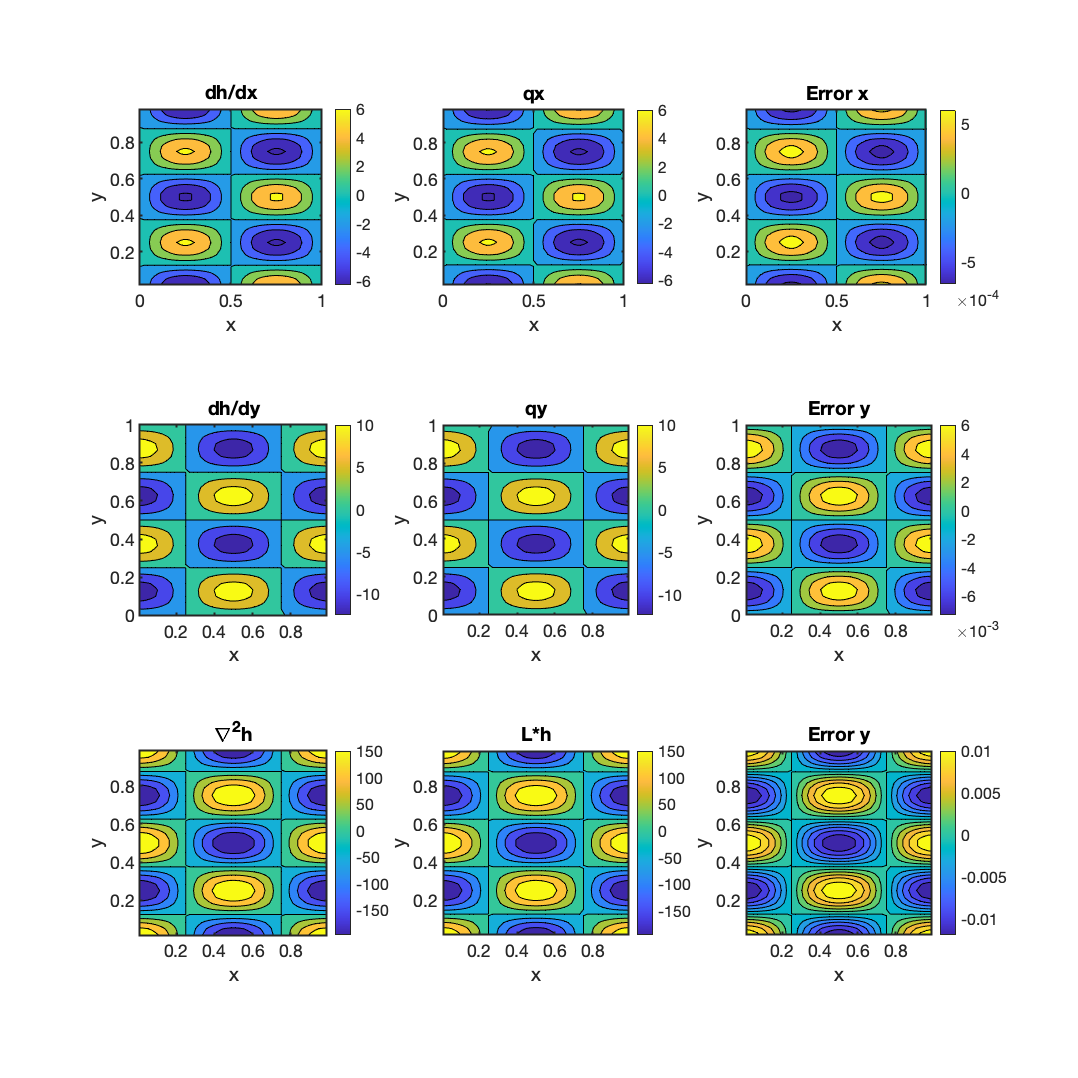

% Define the computational grid
Grid.xmin = 0; Grid.xmax = Lx; Grid.Nx = 50; 
Grid.ymin = 0; Grid.ymax = Ly; Grid.Ny = 30; 
Grid = build_grid(Grid);

[Xc,Yc] = meshgrid(Grid.xc,Grid.yc);     % 2D coords of cell centers
[Xx,Yx] = meshgrid(Grid.xf,Grid.yc);     % 2D coords of x-faces
[Xy,Yy] = meshgrid(Grid.xc,Grid.yf);     % 2D coords of y-faces

% Generate operators
[D,G,~,I,~] = build_ops(Grid);

%% Numerical derivatives
q = G*h(Xc(:),Yc(:));
QX = reshape(q(1:Grid.Nfx),Grid.Ny,Grid.Nx+1);
QY = reshape(q(Grid.Nfx+1:Grid.Nf),Grid.Ny+1,Grid.Nx);
Lap_num = reshape(-D*q,Grid.Ny,Grid.Nx);

figure('name','Testing 2D Operators','position',[10 10 1500 1500])
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot 331
contourf(Xx,Yx,dhdx(Xx,Yx)), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight
title 'dh/dx'

subplot 332
contourf(Xx,Yx,QX), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight
title 'qx'

subplot 333
temp = dhdx(Xx,Yx);
err = (dhdx(Xx,Yx) - QX)/max(temp(:));
contourf(Xx,Yx,err), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight
title 'Error x'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot 334
contourf(Xy,Yy,dhdy(Xy,Yy)), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight
title 'dh/dy'

subplot 335
contourf(Xy,Yy,QY), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight
title 'qy'

subplot 336
temp = dhdy(Xy,Yy);
err = (temp - QY)/max(temp(:));
contourf(Xy,Yy,err), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight
title 'Error y'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
subplot 337
contourf(Xc,Yc,Lap_h(Xc,Yc)), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight
title '\nabla^2h'

subplot 338
contourf(Xc,Yc,Lap_num), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight
title 'L*h'

subplot 339
temp = Lap_h(Xc,Yc);
err = (temp - Lap_num)/max(temp(:));
contourf(Xc,Yc,err), colorbar
axis([0 Grid.Lx 0 Grid.Ly])
xlabel 'x', ylabel 'y'
axis equal tight

title 'Error y'

## Convergence of the approximation

We can also test the convergence of the full numerical solution as we refine the grid. We use the classic 2D analytic solution for 'topography-driven flow' from bt Toth.

%% Physical problem parameters
Length = 200;     % [m] - width of the valley
dh = 15;          % [m] - 1/2 depth of the valley
Height = 50;      % [m] - aquifer thickness
K = 2e-7;        % [m/s] - background conductivity

%% Analytic solution
hana = @(x,z) Height + dh * cos(2*pi*x/Length).*cosh(2*pi*z/Length)/cosh(2*pi*Height/Length);
n = [1 5 10 15 20 25 30];
for i=1:length(n)
    tic
    %% Set up grid and operators
    Grid.xmin = 0; Grid.xmax = Length; Grid.Nx = n(i)*80;
    Grid.ymin = 0; Grid.ymax = Height; Grid.Ny = n(i)*20;
    Grid = build_grid(Grid);
    fprintf('Solving for N = %d\n',Grid.N)
    %% Set boundary conditions
    BC.dof_dir = Grid.dof_ymax; BC.dof_f_dir = Grid.dof_f_ymax;
    BC.g = hana(Grid.xc,Height-Grid.dy/2);
    BC.dof_neu = []; BC.dof_f_neu = []; BC.qb = [];
    
    %% Discrete differential operators
    [D,G,~,I,~] = build_ops(Grid);
    L = -D*K*G;  fs = spalloc(Grid.N,1,0);
    
    %% Build boundary operators
    [B,N,fn] = build_bnd(BC,Grid,I);
    
    %% Solve system
    h = solve_lbvp(L,fs+fn,B,BC.g,N);
    [Xc,Yc] = meshgrid(Grid.xc,Grid.yc);
    
    %% Compute error
    e(i) = norm(h-hana(Xc(:),Yc(:)))/norm(hana(Xc(:),Yc(:)));
    dx(i) = Grid.dx;
    N_dof(i) = Grid.N;
    Nx_dof(i) = Grid.Nx;
    time(i) = toc;
end

Solving for N = 1600
Solving for N = 40000
Solving for N = 160000
Solving for N = 360000
Solving for N = 640000
Solving for N = 1000000
Solving for N = 1440000


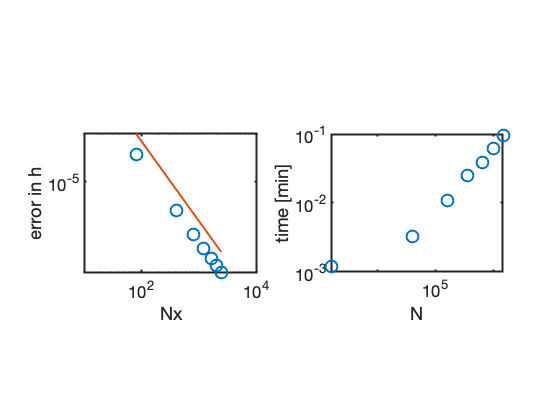


%%
close all
subplot 121
loglog(Nx_dof,e,'o'), hold on
semilogy(Nx_dof,1e-2*Nx_dof.^(-2)*1e2,'-')
xlabel('Nx'), xlim([1e1,1e4])
ylabel('error in h')
pbaspect([1 .8 1])

subplot 122
loglog(N_dof,time/60,'o')
xlabel('N')
ylabel('time [min]')
pbaspect([1 .8 1])

# Auxillary functions

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

## plot_grid()

function [] = plot_grid(Nx,Ny)
N = Nx*Ny;

x = 1:Nx;
y = 1:Ny;
dof = 1:N;

[X,Y] = meshgrid(x,y);

DOF = reshape(dof,Ny,Nx);

plot([.5 Nx+.5 Nx+.5 .5 .5],[.5 .5 Ny+.5 Ny+.5 .5],'k'), hold on
for i=1:Nx
    plot([x(i)+.5 x(i)+.5],[.5 Ny+.5],'k-')
    for j=1:Ny
        plot([.5 Nx+.5],[y(j)+.5 y(j)+.5],'k-')
        plot(X(j,i),Y(j,i),'ro','markerfacecolor','w')
        text(X(j,i)+.1,Y(j,i)+.07,num2str(DOF(j,i)),'fontsize',18,'color','r')
    end
end
set(gca,'xtick',[1:Nx],'ytick',[1:Ny])
axis equal tight 
xlabel 'x-direction'
ylabel 'y-direction'
end